cd(fileparts(matlab.desktop.editor.getActiveFilename))
close all; clearvars; clc

cd("../data-engineering")
load("../../temp-data/participant_list.mat")
cd(fileparts(matlab.desktop.editor.getActiveFilename))

kdf_augmented = participant_array(4).cond_dict('par').task_dict{'ml'}.data_ttbl

kdf_augmented = 8153×16 timetable
      Time        NIP Time       Trial           Gesture               Targets            Features            Kalman 01                Kalman 02                Kalman 03                Kalman 04                Kalman 05                Kalman 06                Kalman 07                Kalman 08                Kalman 09                Kalman 10                                   Kinematics                          
    _________    __________    __________    _______________    _____________________    ___________    _____________________    _____

p_id = 08;
ctrlr_str = "ml";
table_filepath = sprintf("..\\..\\temp-data\\p_%02d-%s\\p_%02d-%s-kdf-mav-gesture_idxs.csv", p_id, ctrlr_str, p_id, ctrlr_str)

table_filepath = "..\..\temp-data\p_08-ml\p_08-ml-kdf-mav-gesture_idxs.csv"

T = readtable(table_filepath)

T = 10×4 table
    gesture_a_starts_idx    gesture_a_stops_idx    gesture_b_starts_idx    gesture_b_stops_idx
    ____________________    ___________________    ____________________    ___________________

               1                    348                     348                    694        
             818                   1164                    1165                   1511        
            1635                   1981                    1982                   2311        
            2434                   2781                    2782                   3128        
            3251                   3598                    3598                   3944        
            4068                   4414                    4415                   4761        
            4885                   5231                    5232                   5578  

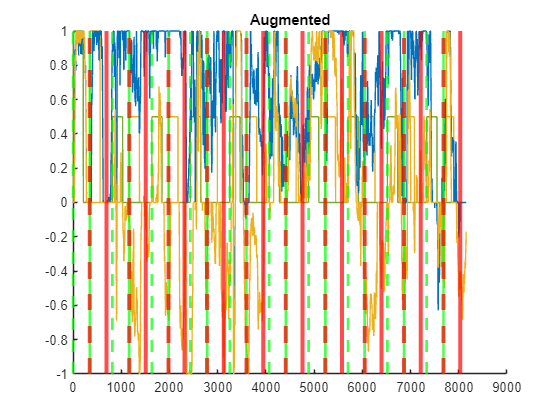

figure
hold on
plot(kdf_augmented{:, "Targets"})
plot(kdf_augmented{:, "Kalman 01"})
xline(T{:,"gesture_a_starts_idx"}, 'g--', LineWidth=2)
xline(T{:,"gesture_b_starts_idx"}, 'g', LineWidth=2)
xline(T{:,"gesture_a_stops_idx"}, 'r--', LineWidth=3)
xline(T{:,"gesture_b_stops_idx"}, 'r', LineWidth=3)
hold off
title("Augmented")

kdf_melted = kdf_augmented(:, ["NIP Time", "Targets", "Features", "Kalman 01", "Kinematics"])

kdf_melted = 8153×5 timetable
      Time        NIP Time            Targets            Features            Kalman 01                                   Kinematics                          
    _________    __________    _____________________    ___________    _____________________    _____________________________________________________________

    0 sec        5.0897e+06    0    0    0    0    0    1×32 double    0    0    0    0    0            0            0            0            0            0
    0.033 sec    5.0902e+06    0    0    0    0    0    1×32 double    0    0    0    0    0            0            0            0            0            0
    0.066 sec    5.0911e+06    1    1    1    1    1    1×32 double    0    0    0

kdf_melted = renamevars(kdf_melted, ["Features", "Kalman 01"], ["MAV Features", "Kalman"])

kdf_melted = 8153×5 timetable
      Time        NIP Time            Targets           MAV Features           Kalman                                     Kinematics                          
    _________    __________    _____________________    ____________    _____________________    _____________________________________________________________

    0 sec        5.0897e+06    0    0    0    0    0    1×32 double     0    0    0    0    0            0            0            0            0            0
    0.033 sec    5.0902e+06    0    0    0    0    0    1×32 double     0    0    0    0    0            0            0            0            0            0
    0.066 sec    5.0911e+06    1    1    1    1    1    1×32 double     0    0

for i = 2:height(T)
    kdf_melted(T.gesture_a_starts_idx(i):T.gesture_b_stops_idx(i), "Kalman") = kdf_augmented(T.gesture_a_starts_idx(i):T.gesture_b_stops_idx(i), sprintf("Kalman %02d", i-1));
end

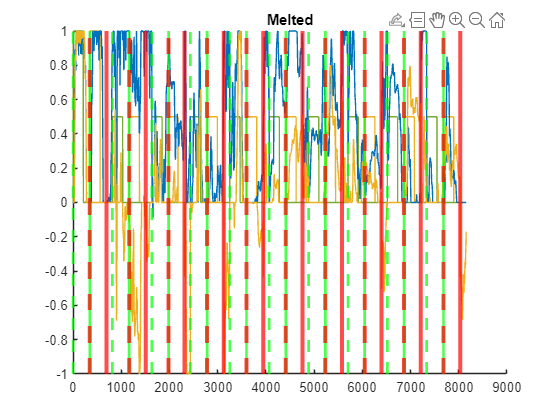

figure
hold on
plot(kdf_melted{:, "Targets"})
plot(kdf_melted{:, "Kalman"})
xline(T{:,"gesture_a_starts_idx"}, 'g--', LineWidth=2)
xline(T{:,"gesture_b_starts_idx"}, 'g', LineWidth=2)
xline(T{:,"gesture_a_stops_idx"}, 'r--', LineWidth=3)
xline(T{:,"gesture_b_stops_idx"}, 'r', LineWidth=3)

hold off
title("Melted")

csv_filename = sprintf('..\\..\\temp-data\\p_%02d-%s\\p_%02d-%s-kdf-mav.csv', p_id, ctrlr_str, p_id, ctrlr_str)

csv_filename = '..\..\temp-data\p_08-ml\p_08-ml-kdf-mav.csv'

writetimetable(kdf_melted, csv_filename)